# Informe de lab 

q = sym('q',[1 6]);

$T_1^0$:

T0_1=simplify(MTH(0,sym (pi/2),45,q(1)))

$$T0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & 45\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$T_2^1$:

T1_2=simplify(MTH(105.4,0,0,q(2)))

$$T1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 105.4000\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 105.4000\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$T_3^2$:

T2_3=simplify(MTH(97,0,0,q(3)))

$$T2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & 97\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 97\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


$$T_4^3$$


T3_4=simplify(MTH(90,0,0,q(4)))

$$T3\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & 90\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 90\,\sin\left(q_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Cuarto: Se determina la matriz $T_4^0$:

$T_4^0$=$T_1^0$$T_2^1$$T_3^2$$T_4^3$

T0_TCP=vpa(simplify(T0_1*T1_2*T2_3*T3_4));
x=T0_TCP(1,4),y=T0_TCP(2,4),z=T0_TCP(3,4)

$$x = 0.2000\,\cos\left(q_{1}\right)\,\left(450\,\cos\left(q_{2}+q_{3}+q_{4}\right)+485\,\cos\left(q_{2}+q_{3}\right)+527\,\cos\left(q_{2}\right)\right)$$

$$y = 0.2000\,\sin\left(q_{1}\right)\,\left(450\,\cos\left(q_{2}+q_{3}+q_{4}\right)+485\,\cos\left(q_{2}+q_{3}\right)+527\,\cos\left(q_{2}\right)\right)$$

$$z = 90\,\sin\left(q_{2}+q_{3}+q_{4}\right)+97\,\sin\left(q_{2}+q_{3}\right)+105.4000\,\sin\left(q_{2}\right)+45$$

R = sym('r_%d_%d',3)==T0_TCP(1:3,1:3);
for i=1:numel(R)
disp(R(i))
end

$$r_{1,1}=\cos\left(q_{2}+q_{3}+q_{4}\right)\,\cos\left(q_{1}\right)$$

$$r_{2,1}=\cos\left(q_{2}+q_{3}+q_{4}\right)\,\sin\left(q_{1}\right)$$

$$r_{3,1}=\sin\left(q_{2}+q_{3}+q_{4}\right)$$

$$r_{1,2}=-1\,\sin\left(q_{2}+q_{3}+q_{4}\right)\,\cos\left(q_{1}\right)$$

$$r_{2,2}=-1\,\sin\left(q_{2}+q_{3}+q_{4}\right)\,\sin\left(q_{1}\right)$$

$$r_{3,2}=\cos\left(q_{2}+q_{3}+q_{4}\right)$$

$$r_{1,3}=\sin\left(q_{1}\right)$$

$$r_{2,3}=-1\,\cos\left(q_{1}\right)$$

$$r_{3,3}=0$$

Las expresiones son tan largas que se salen del margen de pdf, se intentó simplificar las expresiones lo máximo posible, por lo que para visualizar las expresiones completas se pide visualizar el código ejecutado en matlab. 

Quinto: Se determina los valores de la matriz teniedno en cuenta $q=\left\lbrack \;0\;0\;0\;0\;\right\rbrack \;\;$

q1=0; q2=0; q3=0; q4=0;
T0_TCP = round(subs(T0_TCP),5);
x = T0_TCP(1,4), y = T0_TCP(2,4)    , z = T0_TCP(3,4)

$$x = 292.4000$$

$$y = 0$$

$$z = 45$$

R=T0_TCP(1:3,1:3)

$$R = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & -1\\ 0 & 1 & 0 \end{array}\right)$$

Gráficas


q=[-pi/9,pi/2-pi/9,-pi/9-pi/2,pi/9]

q =    -0.3491    1.2217   -1.9199    0.3491




%Caso 1
R1 = Link([0 0.45 0 pi/2]);
R2 = Link([pi/2 0 1.054 0]);
R3 = Link([-pi/2 0 0.97 0]);
R4 = Link([0 0 0.90 0]);

M2 = SerialLink([R1; R2; R3; R4], 'name', 'q0');
%Caso 2
R1 = Link([q(1) 0.45 0 pi/2]);
R2 = Link([q(2) 0 1.054 0]);
R3 = Link([q(3) 0 0.97 0]);
R4 = Link([q(4) 0 0.90 0]);
M2_2 = SerialLink([R1; R2; R3; R4], 'name', 'q1');

q2=[pi/6,pi/2--pi/6,pi/6-pi/2,-pi/6]

q2 =     0.5236    2.0944   -1.0472   -0.5236


R1 = Link([q(1) 0.45 0 pi/2]);
R2 = Link([q(2) 0 1.054 0]);
R3 = Link([q(3) 0 0.97 0]);
R4 = Link([q(4) 0 0.90 0]);
M2_3 = SerialLink([R1; R2; R3; R4], 'name', 'q2');

q3=[-pi/2,pi/2-pi/12,-pi*55/180-pi/2,pi*17/180]

q3 =    -1.5708    1.3090   -2.5307    0.2967


R1 = Link([q(1) 0.45 0 pi/2]);
R2 = Link([q(2) 0 1.054 0]);
R3 = Link([q(3) 0 0.97 0]);
R4 = Link([q(4) 0 0.90 0]);
M2_4 = SerialLink([R1; R2; R3; R4], 'name', 'q3');

q4=[-pi/2,pi/2-pi/4,-pi*55/180-pi/2,pi/4]

q4 =    -1.5708    0.7854   -2.5307    0.7854


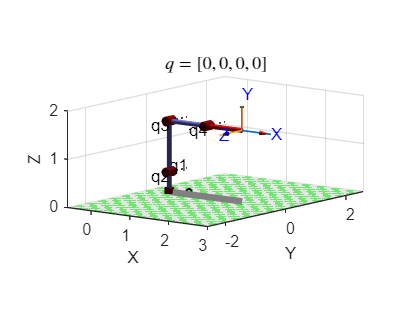

R1 = Link([q(1) 0.45 0 pi/2]);
R2 = Link([q(2) 0 1.054 0]);
R3 = Link([q(3) 0 0.97 0]);
R4 = Link([q(4) 0 0.90 0]);
M2_5 = SerialLink([R1; R2; R3; R4], 'name', 'q4');
%Se grafican ambas configuraciones

figure()
title('$$q=[0,0,0,0]$$','interpreter','latex','fontSize',11)
M2.plot([0 pi/2 -pi/2 0] ,'workspace',[-0.5 3 -2.5 2.5 0 2],'jaxes','linkcolor',[0.5 0.5 1])
view([37.82 9.87])

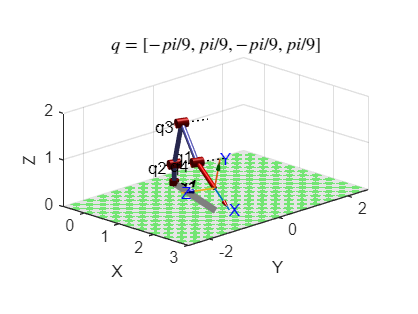


figure()
title('$$q=[-pi/9,pi/9,-pi/9,pi/9]$$',...
'interpreter','latex','fontSize',11)
M2_2.plot(q,'workspace',[-0.5 3 -2.5 2.5 0 2],'jaxes','linkcolor',[0.5 0.5 1])
view([45 18])

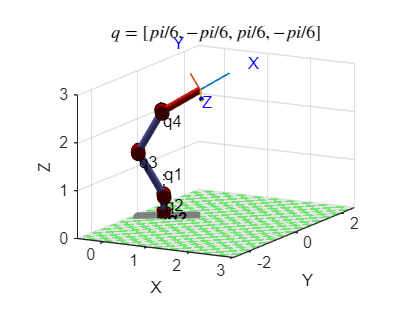


figure()
title('$$q=[pi/6,-pi/6,pi/6,-pi/6]$$','interpreter','latex','fontSize',11)
M2_3.plot(q2,'workspace',[-0.5 3 -2.5 2.5 0 3],'jaxes','linkcolor',[0.5 0.5 1])
view([28.17 12.72])

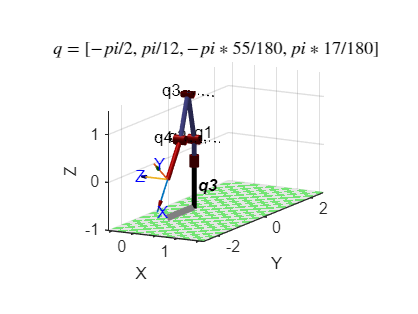


figure()
title('$$q=[-pi/2,pi/12,-pi*55/180,pi*17/180]$$',...
'interpreter','latex','fontSize',11)
M2_4.plot(q3,'workspace',[-0.5 1.5 -2.5 2.5 -1 1.5],'jaxes','linkcolor',[0.5 0.5 1])
view([28.17 12.72])

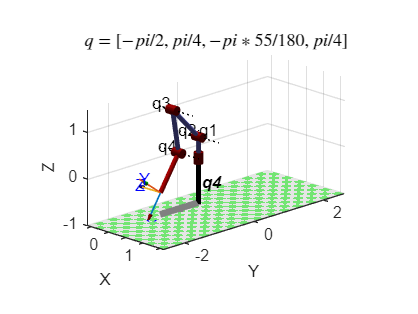

figure()
title('$$q=[-pi/2,pi/4,-pi*55/180,pi/4]$$',...
'interpreter','latex','fontSize',11)
M2_5.plot(q4,'workspace',[-0.5 1.5 -2.5 2.5 -1 1.5],'jaxes','linkcolor',[0.5 0.5 1])
view([45 18])